clear all
close all
clc

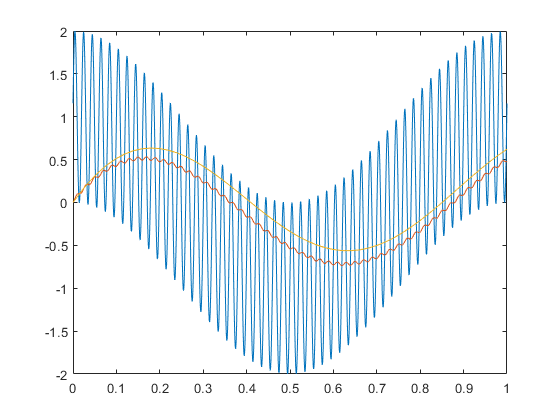

% signal
fc = 1;
phi = pi / 2;
mu = 2 * pi * fc;

Ts = 0.02;

% noise
fc_noise = 50;
phi_noise = pi / 2 * 0.1;
mu_noise = 2 * pi * fc_noise;

% data creation
t = 0:0.00001:1;
u = sin(mu * t + phi);
e0 = sin(mu_noise * t + phi_noise);
y = u + e0;

td = 0:Ts:1;
ud = sin(mu * td + phi);
e0d = sin(mu_noise * td + phi_noise);
yd = ud + e0d;

% filtering
mu0 = mu;
s = tf('s');
H = mu0 / ( s + mu0 );
y_hat = lsim(H, y, t);

Hd = c2d(H, Ts, 'zoh');
yd_hat = lsim(Hd, yd, td);

plot(t, y)
hold on
plot(t, y_hat)
plot(td, yd_hat)


Hd

Hd =
 
    0.1181
  ----------
  z - 0.8819
 
Sample time: 0.02 seconds
Discrete-time transfer function.

